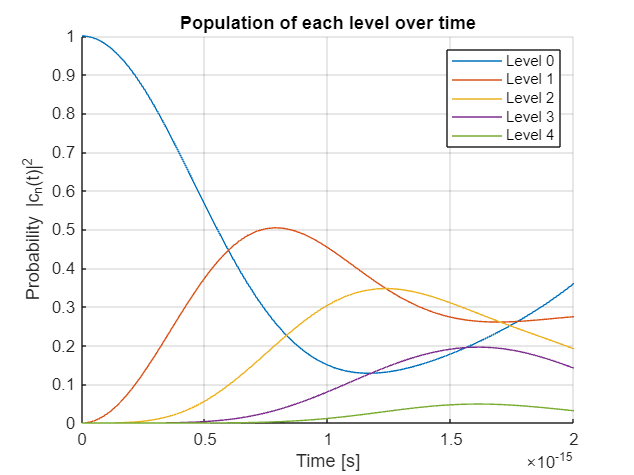

% Question 2 - MATLAB Code 

% Parameters  
N = 5;
V = 1;                                  % [eV]
w_a = 1;                                % [1/s]
En = (0:N-1);                           % [eV]
h_bar = 6.5821158843376e-16;            % [eV*s], reduced Planck's constant
tspan = [0, 2e-15];                     % [s], Define the simulation time period
                                        %      It looks good between 1e-15 and 5e-15

% Initial Conditions 
C0 = zeros(N, 1);                       % Column of zeros (N×1) – representing the state at time at t=0
C0(1) = 1;                              % At t=0 only the first level is fully populated 

% Equation Solving
dcdt = @(t, C) numeric_equation(t, C, En, V, w_a, N, h_bar); % Calling the main function with all parameters needed
[t, Csol] = ode45(dcdt, tspan, C0); % The solution of the system of differential equations
                                    % By default – not fixed number of samples.
                                    % ode45 chooses the points like this:
                                    % Where the solution changes quickly - many points.
                                    % Where the solution is smooth - fewer points.

% Auxiliary function 
function dCdt = numeric_equation(t, C, En, V0, omega, N, hbar)
    % Define the Hamiltonian parts
    H0 = diag(En);              % Time independent part - diagonal Hamiltonian: H_ij = E_n * δ_ij
    Vt = V0 * cos(omega * t);   % Time-dependent - interaction (off-diagonal)
    V_matrix = diag(Vt * ones(N-1,1), 1) + diag(Vt * ones(N-1,1), -1);
    H = H0 + V_matrix;          % Total Hamiltonian

    % Schrodinger equation
    dCdt = (-1i / hbar) * H * C;
end


% Figure The Population Of Each Level |c_n(t)|^2
figure;
hold on;
for n = 1:N
    plot(t, abs(Csol(:,n)).^2, 'DisplayName', ['Level ' num2str(n-1)]);
end
xlabel('Time [s]');
ylabel('Probability |c_n(t)|^2');
legend;
title('Population of each level over time');
grid on;